# Live Script in project Is Camel Case

Is a sequence a travel in a mesh

clear all
close('all')

## Extract Travels from Models

NofStartsInModel = 100;
RunLengthFraction = 0.5;
R = RandStream("mlfg6331_64","Seed",0);
MainFolder = fullfile("outputs","models");
Table = readtable(fullfile(MainFolder,"SimplifiedModels.xlsx"),"ReadVariableNames",true,"PreserveVariableNames",true);
Table.name = string(Table.name);
Table.reducedName = "M"+Table.index+".stl";
Table.folder = categorical(string(Table.folder));

Travels = cell(NofStartsInModel*height(Table),1);
Types   = repmat(categorical("model"),numel(Travels),1);
Counter = 0;
for t=1:height(Table)
    Model = stlread(fullfile(MainFolder,Table.reducedName(t)));
    Points = Model.Points - min(Model.Points);
    Points = Points ./ max(Model.Points);
%     List = [ Model.ConnectivityList(:,[1 2]);
%              Model.ConnectivityList(:,[2 1]);
%              Model.ConnectivityList(:,[2 3]);
%              Model.ConnectivityList(:,[3 2]);
%              Model.ConnectivityList(:,[1 3]);
%              Model.ConnectivityList(:,[3 1])];
%     List = List(List(:,1)>List(:,2),:);
%     G = graph(List(:,1),List(:,2));
    if Table.folder(t)=="teethwrl"
        Types(Counter+(1:NofStartsInModel)) = categorical("teeth");
    end
%     StartPoints = R.randi(size(G.Nodes,1), NofStartsInModel ,1);
    StartPoints = R.randi(size(Points,1), NofStartsInModel ,1);
    for iStart = StartPoints'
        Counter=Counter+1;
        Travel = FindTravel( Model.ConnectivityList ...
            ,Points ...
            ,iStart ...
            ,ceil(size(Points,1)*RunLengthFraction) ...
            ,R) ;
        Travels{Counter} = Points(Travel,:);
        % S = bfsearch(G,iStart,"Restart",true);
        % Travels{Counter} = Points(S,:);
    end
    disp("- calculated all travels on model " + t)
end

- calculated all travels on model 1
- calculated all travels on model 2
- calculated all travels on model 3
- calculated all travels on model 4
- calculated all travels on model 5
- calculated all travels on model 6
- calculated all travels on model 7
- calculated all travels on model 8
- calculated all travels on model 9
- calculated all travels on model 10
- calculated all travels on model 11
- calculated all travels on model 12
- calculated all travels on model 13
- calculated all travels on model 14
- calculated all travels on model 15
- calculated all travels on model 16
- calculated all travels on model 17
- calculated all travels on model 18
- calculated all travels on model 19
- calculated all travels on model 20
- calculated all travels on model 21
- calculated all travels on model 22
- calculated all travels on model 23
- calculated all travels on model 24
- calculated all travels on model 25
- calculated all travels on model 26
- calculated all travels on model 27
- calculat

Noise = InventNoise(R,Travels);

save("TravelsAndNoise.mat","Travels","Types","Noise",'-v7.3');

clear all
close('all')
load("TravelsAndNoise.mat","Travels","Types");

t = 2703

t = 2703

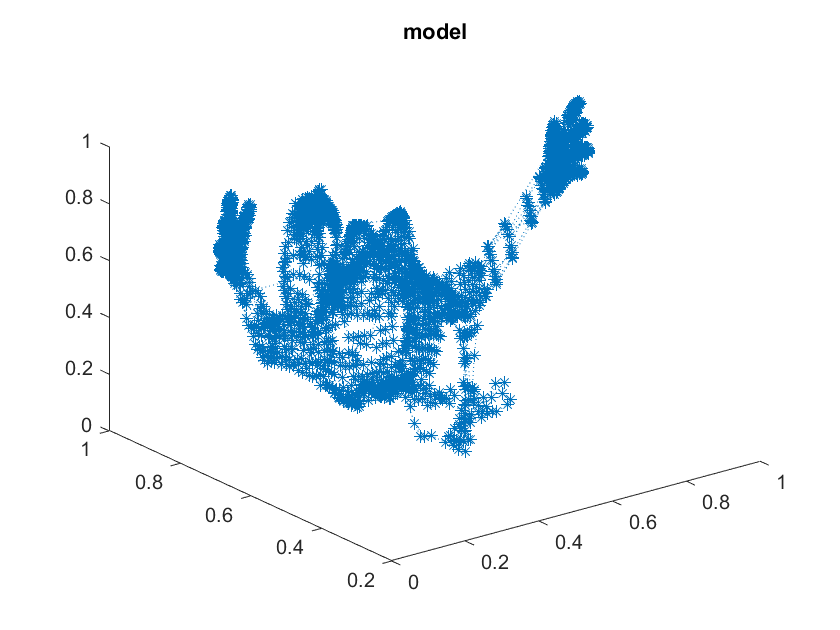

clf
Points = Travels{t};
plot3(Points(:,1),Points(:,2),Points(:,3),':*')        
title(string(Types(t)))    

## Start with Canned Example

clear all
close('all')

load("TravelsAndNoise.mat","Travels","Types","Noise");

X-data are the dX,dY,dZ of each travel

Y-data are the categories: Noise, model, [teeth], small

XData = Travels;
YData = Types;
N = cellfun(@(c)size(c,1),XData);
YData(N<1000)=categorical("small");
YData = [YData;          
         repmat(categorical("Noise"),numel(Noise),1)];
XData = cellfun(@(c)c',[XData; Noise],"UniformOutput",false);



|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:01 |       10.94% |       1.3873 |          0.0010 |


|       1 |          50 |       00:00:59 |       59.38% |       0.9517 |          0.0010 |


|       1 |         100 |       00:01:56 |       78.13% |       0.5398 |          0.0010 |


|       2 |         150 |       00:02:55 |       74.22% |       0.4818 |          0.0010 |


|       2 |         200 |       00:03:53 |       82.81% |       0.4813 |          0.0010 |


|       3 |         250 |       00:04:52 |       74.22% |       0.4020 |          0.0010 |


|       3 |         300 |       00:05:51 |       79.69% |       0.3687 |          0.0010 |


|       4 |         350 |       00:06:48 |       82.81% |       0.3529 |          0.0010 |


|       4 |         400 |       00:07:47 |       88.28% |       0.3384 |          0.0010 |


|       5 |         450 |       00:08:47 |       85.16% |       0.2907 |          0.0010 |


|       5 |         500 |       00:09:45 |       82.81% |       0.3043 |          0.0010 |


|       5 |         550 |       00:10:44 |       82.81% |       0.3337 |          0.0010 |


|       6 |         600 |       00:11:41 |       89.84% |       0.2434 |          0.0010 |


|       6 |         650 |       00:12:38 |       92.19% |       0.2048 |          0.0010 |


|       7 |         700 |       00:13:38 |       86.72% |       0.2964 |          0.0010 |


|       7 |         750 |       00:14:35 |       87.50% |       0.2618 |          0.0010 |


|       8 |         800 |       00:15:33 |       85.94% |       0.3237 |          0.0010 |


|       8 |         850 |       00:16:32 |       91.41% |       0.2551 |          0.0010 |


|       9 |         900 |       00:17:30 |       87.50% |       0.2461 |          0.0010 |


|       9 |         950 |       00:18:29 |       82.81% |       0.3401 |          0.0010 |


|       9 |        1000 |       00:19:26 |       86.72% |       0.2772 |          0.0010 |


|      10 |        1050 |       00:20:25 |       90.63% |       0.2043 |          0.0010 |


|      10 |        1100 |       00:21:22 |       86.72% |       0.2400 |          0.0010 |


|      11 |        1150 |       00:22:21 |       89.84% |       0.1751 |          0.0010 |


|      11 |        1200 |       00:23:20 |       88.28% |       0.2338 |          0.0010 |


|      12 |        1250 |       00:24:17 |       88.28% |       0.2901 |          0.0010 |


|      12 |        1300 |       00:25:14 |       91.41% |       0.1683 |          0.0010 |


|      13 |        1350 |       00:26:13 |       94.53% |       0.1584 |          0.0010 |


|      13 |        1400 |       00:27:11 |       89.06% |       0.2227 |          0.0010 |


|      13 |        1450 |       00:28:09 |       89.06% |       0.2080 |          0.0010 |


|      14 |        1500 |       00:29:07 |       87.50% |       0.3038 |          0.0010 |


|      14 |        1550 |       00:30:06 |       90.63% |       0.2213 |          0.0010 |


|      15 |        1600 |       00:31:05 |       90.63% |       0.1924 |          0.0010 |


|      15 |        1650 |       00:32:02 |       95.31% |       0.1213 |          0.0010 |


|      16 |        1700 |       00:33:00 |       94.53% |       0.1557 |          0.0010 |


|      16 |        1750 |       00:33:59 |       82.81% |       0.3002 |          0.0010 |


|      17 |        1800 |       00:34:59 |       94.53% |       0.1410 |          0.0010 |


|      17 |        1850 |       00:35:54 |       89.06% |       0.2247 |          0.0010 |


|      17 |        1900 |       00:36:53 |       92.97% |       0.1581 |          0.0010 |


|      18 |        1950 |       00:37:50 |       95.31% |       0.1353 |          0.0010 |


|      18 |        2000 |       00:38:48 |       97.66% |       0.1372 |          0.0010 |


|      19 |        2050 |       00:39:45 |       92.97% |       0.1787 |          0.0010 |


|      19 |        2100 |       00:40:42 |       95.31% |       0.1200 |          0.0010 |


|      20 |        2150 |       00:41:40 |       93.75% |       0.1850 |          0.0010 |


|      20 |        2200 |       00:42:39 |       91.41% |       0.2456 |          0.0010 |


|      21 |        2250 |       00:43:36 |       95.31% |       0.1331 |          0.0010 |


|      21 |        2300 |       00:44:32 |       95.31% |       0.1052 |          0.0010 |


|      21 |        2350 |       00:45:30 |       94.53% |       0.1677 |          0.0010 |


|      22 |        2400 |       00:46:27 |       95.31% |       0.1127 |          0.0010 |


|      22 |        2450 |       00:47:25 |       93.75% |       0.1249 |          0.0010 |


|      23 |        2500 |       00:48:22 |       95.31% |       0.0774 |          0.0010 |


|      23 |        2550 |       00:49:20 |       96.09% |       0.0898 |          0.0010 |


|      24 |        2600 |       00:50:19 |       91.41% |       0.1993 |          0.0010 |


|      24 |        2650 |       00:51:16 |       92.97% |       0.1559 |          0.0010 |


|      25 |        2700 |       00:52:15 |       96.09% |       0.0979 |          0.0010 |


|      25 |        2750 |       00:53:15 |       96.88% |       0.1154 |          0.0010 |


|      25 |        2800 |       00:54:11 |       98.44% |       0.0435 |          0.0010 |


|      26 |        2850 |       00:55:09 |       92.97% |       0.1799 |          0.0010 |


|      26 |        2900 |       00:56:07 |       98.44% |       0.0602 |          0.0010 |


|      27 |        2950 |       00:57:06 |      100.00% |       0.0160 |          0.0010 |


|      27 |        3000 |       00:58:06 |       97.66% |       0.0897 |          0.0010 |


|      28 |        3050 |       00:59:04 |       96.88% |       0.1021 |          0.0010 |


|      28 |        3100 |       01:00:02 |       97.66% |       0.0409 |          0.0010 |


|      29 |        3150 |       01:01:00 |       99.22% |       0.0285 |          0.0010 |


|      29 |        3200 |       01:01:59 |       98.44% |       0.0675 |          0.0010 |


|      30 |        3250 |       01:02:58 |       94.53% |       0.1615 |          0.0010 |


|      30 |        3300 |       01:03:54 |       97.66% |       0.0987 |          0.0010 |


|      30 |        3350 |       01:04:52 |       99.22% |       0.0325 |          0.0010 |


|      31 |        3400 |       01:05:48 |       92.97% |       0.1698 |          0.0010 |


|      31 |        3450 |       01:06:46 |       98.44% |       0.0694 |          0.0010 |


|      32 |        3500 |       01:07:45 |       97.66% |       0.0770 |          0.0010 |


|      32 |        3550 |       01:08:43 |       99.22% |       0.0287 |          0.0010 |


|      33 |        3600 |       01:09:39 |       97.66% |       0.0653 |          0.0010 |


|      33 |        3650 |       01:10:37 |       98.44% |       0.0347 |          0.0010 |


|      34 |        3700 |       01:11:33 |       96.09% |       0.0820 |          0.0010 |


|      34 |        3750 |       01:12:31 |       98.44% |       0.0497 |          0.0010 |


|      34 |        3800 |       01:13:30 |       94.53% |       0.1292 |          0.0010 |


|      35 |        3850 |       01:14:29 |       95.31% |       0.0930 |          0.0010 |


|      35 |        3900 |       01:15:28 |       98.44% |       0.0465 |          0.0010 |


|      36 |        3950 |       01:16:27 |       97.66% |       0.0485 |          0.0010 |


|      36 |        4000 |       01:17:26 |       96.88% |       0.0747 |          0.0010 |


|      37 |        4050 |       01:18:24 |       96.09% |       0.1018 |          0.0010 |


|      37 |        4100 |       01:19:22 |       98.44% |       0.0780 |          0.0010 |


|      38 |        4150 |       01:20:21 |       99.22% |       0.0407 |          0.0010 |


|      38 |        4200 |       01:21:19 |       94.53% |       0.1064 |          0.0010 |


|      38 |        4250 |       01:22:16 |       97.66% |       0.0389 |          0.0010 |


|      39 |        4300 |       01:23:15 |       99.22% |       0.0223 |          0.0010 |


|      39 |        4350 |       01:24:13 |       99.22% |       0.0259 |          0.0010 |


|      40 |        4400 |       01:25:13 |       96.88% |       0.0980 |          0.0010 |


|      40 |        4450 |       01:26:11 |       99.22% |       0.0191 |          0.0010 |


|      41 |        4500 |       01:27:10 |       99.22% |       0.0206 |          0.0010 |


|      41 |        4550 |       01:28:09 |       99.22% |       0.0191 |          0.0010 |


|      42 |        4600 |       01:29:06 |       97.66% |       0.0362 |          0.0010 |


|      42 |        4650 |       01:30:05 |       98.44% |       0.0548 |          0.0010 |


|      42 |        4700 |       01:31:05 |       96.09% |       0.1169 |          0.0010 |


|      43 |        4750 |       01:32:03 |       97.66% |       0.0897 |          0.0010 |


|      43 |        4800 |       01:33:01 |       98.44% |       0.0291 |          0.0010 |


|      44 |        4850 |       01:34:00 |      100.00% |       0.0089 |          0.0010 |


|      44 |        4900 |       01:34:59 |      100.00% |       0.0109 |          0.0010 |


|      45 |        4950 |       01:36:00 |       99.22% |       0.0227 |          0.0010 |


|      45 |        5000 |       01:37:01 |       99.22% |       0.0124 |          0.0010 |


|      46 |        5050 |       01:37:59 |       98.44% |       0.0308 |          0.0010 |


|      46 |        5100 |       01:38:59 |       99.22% |       0.0190 |          0.0010 |


|      46 |        5150 |       01:39:56 |       98.44% |       0.0631 |          0.0010 |


|      47 |        5200 |       01:40:54 |       99.22% |       0.0133 |          0.0010 |


|      47 |        5250 |       01:41:53 |       98.44% |       0.0665 |          0.0010 |


|      48 |        5300 |       01:42:51 |       99.22% |       0.0249 |          0.0010 |


|      48 |        5350 |       01:43:49 |       99.22% |       0.0297 |          0.0010 |


|      49 |        5400 |       01:44:47 |       99.22% |       0.0236 |          0.0010 |


|      49 |        5450 |       01:45:45 |       99.22% |       0.0144 |          0.0010 |


|      49 |        5455 |       01:45:51 |      100.00% |       0.0095 |          0.0010 |
|========================================================================================|


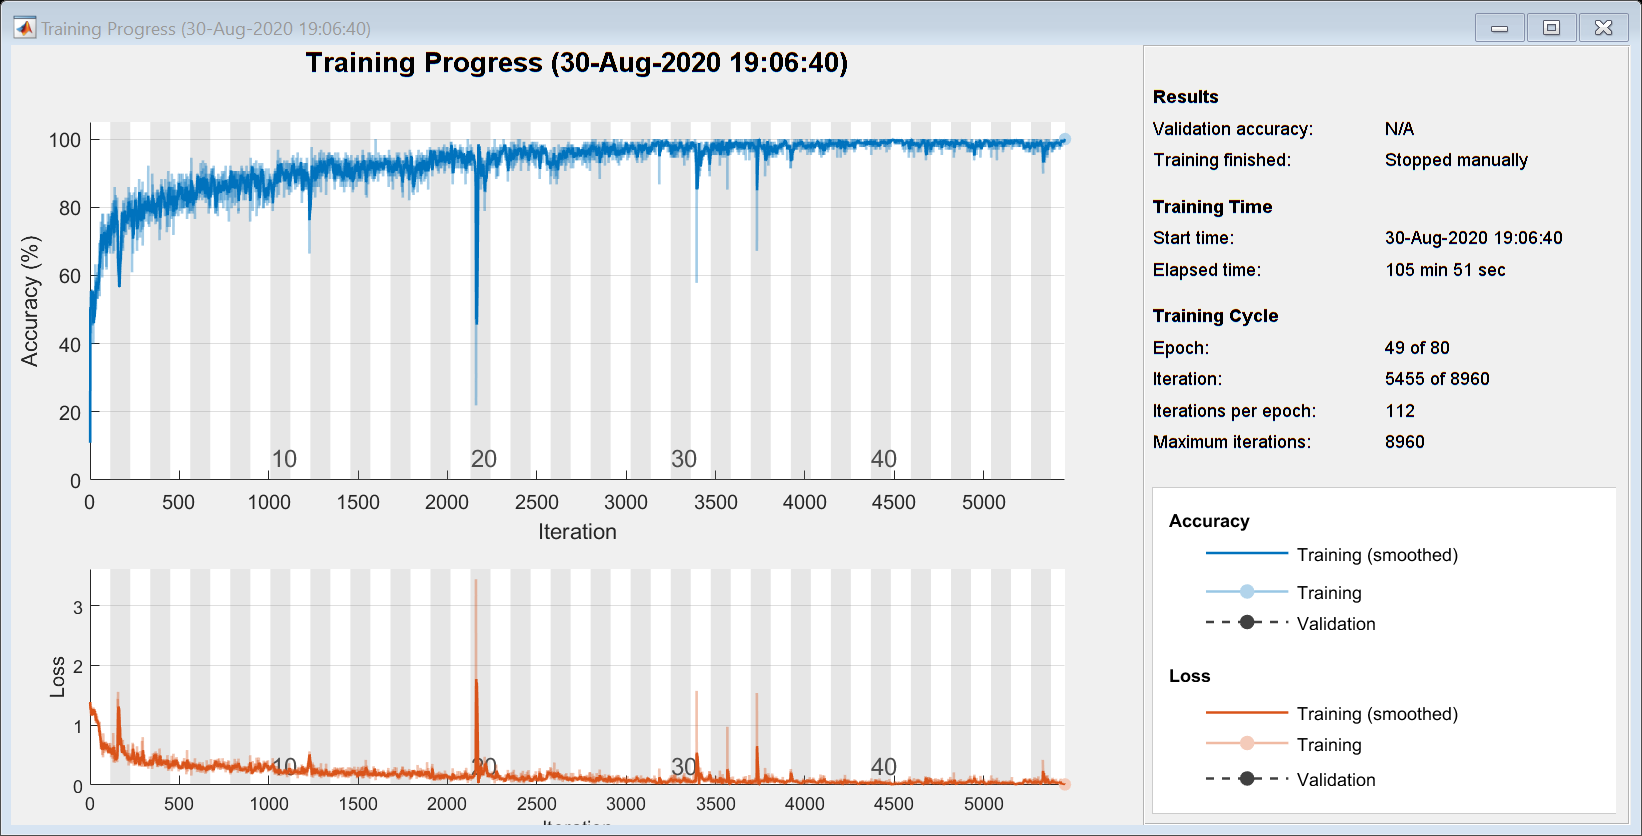

Layers = [ ...
    sequenceInputLayer( 3 )
    fullyConnectedLayer(256)
    bilstmLayer(128)
    bilstmLayer(128,'OutputMode','last')
    fullyConnectedLayer( 4 )
    softmaxLayer
    classificationLayer];

Options = trainingOptions('adam', ...
    'ExecutionEnvironment','gpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs', 80, ...
    'MiniBatchSize', 128, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',1, ...
    'Plots','training-progress');

net = trainNetwork(XData,YData,Layers,Options);

save("TheNet.mat","net")

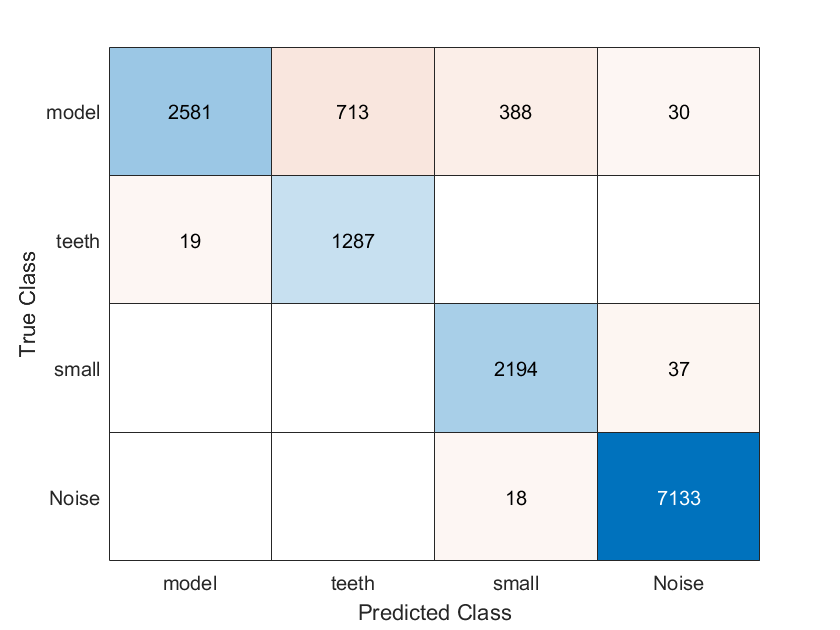

Y=net.classify(XData);
confusionchart(Y,YData)

function Travel = FindTravel(Faces,Points,iStart,RunLength,R)
    arguments
        Faces     (:,3) uint16 % assuming a reduced model at input
        Points    (:,3) single
        iStart    (1,1) uint16
        RunLength (1,1) uint16
        R % randomaizer
    end
    Travel = zeros(RunLength,1,'uint16');
    Index = Faces(iStart);
    
    for i=2:RunLength
        Travel(i-1) = Index;
%        disp("Travel("+(i-1)+")=" + Index)

In which faces can we find this point?    

        PointAt = find(Faces(:)==Index);   
        assert(~isempty(PointAt))
%        disp(numel(PointAt)+" occurences found")

Never visit this point again. 

All faces with just one point become unuseful

        Faces(Faces==Index)=0;
%        disp(nnz(N==0) + "==0, " + nnz(N==1) + "==1, " + nnz(N==2) + "==2")

Not a dead -end. Which face was it?

       [FaceNo,i123] = ind2sub(size(Faces) ...
       ,PointAt(R.randi(numel(PointAt),1,1)));
 %      disp("Selected occurence at " + FaceNo + ", " + i123)

hoose a neighbour

        Others = Faces(FaceNo,setdiff(1:3,i123));
        Others = Others(Others~=0);
        switch numel(Others)
            case 0

Have we reached a dead-end? Must restart from a new [random] nearby point              

                N = sum(uint8(Faces>0),2);        
                Faces = Faces(N>1,:);
                U = unique(Faces(Faces(:)>0));
                dE = sum(abs(Points(U,:)-Points(Index,:)),2);
                Index = U(find(dE==min(dE),1));

%               disp("Dead-end, " + size(Faces,1) + "faces remain, jump to + " + Index)
            case 1
                Index = Others;
            case 2
                Index = Others(R.randi(2,1,1));
        end
%        disp("Selected neighbour " + Index + " of " + numel(Others))
    end
    Travel(RunLength) = Index;
end

function Noise = InventNoise(R,Travels)
    Noise = cell(size(Travels));
    for n=1:numel(Noise)
        Noise{n} = R.randn(size(Travels{n},1),3);
        Noise{n} = Noise{n} - min(Noise{n}); 
        Noise{n} = Noise{n}./ max(Noise{n}); 
    end
end